# Clustering with kNN

read the data zy3sample1

Img = multibandread('zy3sample1',[400,400,4],'float',0,'bsq','n',{'Band','Direct',[1:4]});%将
% % 下面一句话要改成自己的做的GT或者CMap的名字和相应参数。
GT = multibandread('CMap_zy3sample1',[400,400,1],'uint8',0,'bsq','n',{'Band','Direct',[1:1]});%将
test_class=1:4;
C=length(test_class);
NbRow=400;
NbCol=400;
NbDim=4;
dataname='zy3';

parameters in knn

options.K=3;%尝试不同的k值，1,3,5,7,9等。
options.test_class=test_class;
options.measure='SAM';% similarity measurement，尝试欧式距离和光谱角距离

10 iterations and set default prpotion--20% for training data


nrep=3; % 重复3次 experiments.
Sampling=50; % selecting sampling percent data as training data.训练数据的比例

for expt=1:nrep
    
    fprintf(1,'processing on the experiment %d \n',expt);
    Train_row=[];Train_col=[];% Train_row and Train_col is the coordinates of training data
    Test_row=[];Test_col=[];% Test_row and Test_col is the coordinates of testing data
    Y_train=[];Y_test=[];% Y_train is the label of training data(N_train*1); Y_test is the label of testing data(N_test*1);
    X_train=[];X_test=[];% X_train is the training data(N_train*D); X_test is the testing data(N_test*D);
    
    %% 直接在GT中随机选择训练数据和测试数据
    for i=1:length(test_class)
        [row,col]=find(GT==test_class(i));%每一类地物所有像素点的行列坐标
        n(i)=length(row);%每一类地物包含像素点的数量
        temp=randperm(n(i));%随机打乱n(i)个数
        ind_train=temp(1:round(n(i)*Sampling/100));%第i类训练数据个数
        ind_test=temp(round(n(i)*Sampling/100)+1:end);%第i类测试数据个数
        Train_row=[Train_row;row(ind_train)];% 训练数据的row坐标
        Train_col=[Train_col;col(ind_train)];% 训练数据的row坐标
        n_train(i)=round(n(i)*Sampling/100);% 第i类训练数据的个数
        Test_row=[Test_row;row(ind_test)];% 测试数据的row坐标
        Test_col=[Test_col;col(ind_test)];% 测试数据的列坐标
        n_test(i)=n(i)- n_train(i);% 第i类测试数据的个数
        %% 根据行列坐标提取train和test数据
        for j=1:n_train(i) 
            X_train=[X_train;reshape(Img(row(ind_train(j)),col(ind_train(j)),:),1,NbDim)];
        end
        
        for j=1:n_test(i) 
            X_test=[X_test;reshape(Img(row(ind_test(j)),col(ind_test(j)),:),1,NbDim)];
        end
        
        Y_train=[Y_train;repmat(test_class(i),n_train(i),1)];%训练数据的标签
        Y_test=[Y_test;repmat(test_class(i),n_test(i),1)];%测试数据的标签
        
    end
         result=My_KNN(X_train,Y_train,X_test,options.K);
         [fid,OA(expt),ProdAcc(expt,:),Kappa(expt),UserAcc(expt,:)]=confusion_ML(Y_test,result');
end

processing on the experiment 1 




Overall Accuracy: 99.34
Kappa: 98.92

    &   1  &   2  &   3  &   4  
------------------------------------------
  1 & 3530 &    0 &    0 &    3 &  99.9
  2 &    0 & 1955 &    0 &    0 &  100.0
  3 &    0 &    0 &  151 &   16 &  90.4
  4 &    0 &    0 &   26 & 1087 &  97.7
------------------------------------------
    & 100.0 & 100.0 & 85.3 & 98.3 



processing on the experiment 2 




Overall Accuracy: 99.50
Kappa: 99.19

    &   1  &   2  &   3  &   4  
------------------------------------------
  1 & 3530 &    0 &    0 &    0 &  100.0
  2 &    0 & 1955 &    2 &    0 &  99.9
  3 &    0 &    0 &  151 &    8 &  95.0
  4 &    0 &    0 &   24 & 1098 &  97.9
------------------------------------------
    & 100.0 & 100.0 & 85.3 & 99.3 



processing on the experiment 3 




Overall Accuracy: 99.35
Kappa: 98.95

    &   1  &   2  &   3  &   4  
------------------------------------------
  1 & 3530 &    0 &    0 &    1 &  100.0
  2 &    0 & 1955 &    0 &    0 &  100.0
  3 &    0 &    0 &  142 &    8 &  94.7
  4 &    0 &    0 &   35 & 1097 &  96.9
------------------------------------------
    & 100.0 & 100.0 & 80.2 & 99.2 



calculate the average accurayc of the 10 experiments

 OA_ave=mean(OA);
 OA_std=sqrt(var(OA));

classfication for Img file after assessment of training data

reduce the demension of Img 

%  for i=1:NbDim  
%      Img_reduce_dimen(:,i)=reshape(Img(:,:,i),NbRow*NbCol,1);   
%  end

initialize sequence of kNN classification

 for i=1:size(Img,1)  % for each row
   test_i_row=Img(i,:,:);%图像的第i行作为test数据进行分类
   test_i_row=reshape(test_i_row,size(Img,2),NbDim);% size:N*D
   result_img(i,:)=My_KNN(X_train,Y_train,test_i_row,options.K);
 end

画出整个图像的分类结果

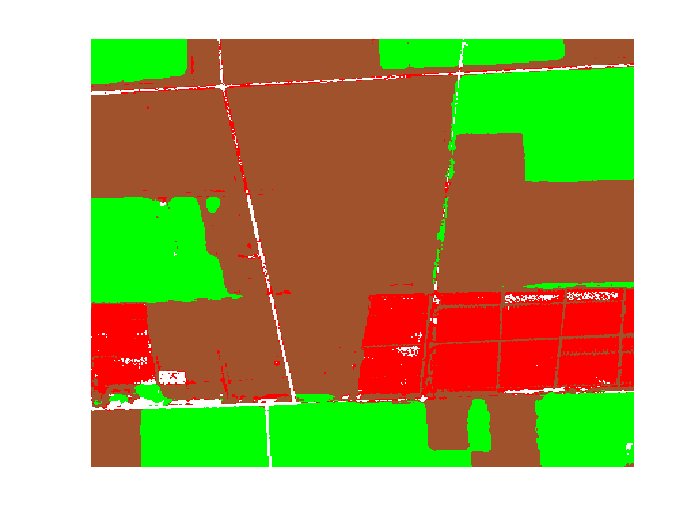

ColorTable=[160,82,45;0 255 0;255, 255, 255;255,0,0];
ClassificationMap  = GenerateClassificationMap( size(Img,1), size(Img,2), ColorTable, reshape(result_img',size(Img,1)*size(Img,2),1));
figure
image(ClassificationMap);  
axis off;